# Minimum Mean Squared Error

% Uplink
% Achievable Rate V.S. Power Parameter
% Linear Formation and Rectangular Formation

## Global Parameter

clc
clearvars

M1 = 8;
M2 = 8;
M = M1 * M2;
K = 10;

taps = 4;

max_c = 40;
range = linspace(0, 20, max_c);

freq = 20;

use = 5;

time = 100;
cyclic = 20;

shield = taps + freq + 1;

IK = eye(K);

r_in = 10;

dn = 0.5;

alpha = 0.7;
eta = 0;
mu = 0;


## Correlation Matrix

for i = 1 : M
    for j = 1 : M
        dist(i, j) = abs(i - j) * dn;
    end
end
exp_1D = alpha .^ dist;
arg = eta ^ 2 - 4 * (pi ^ 2) .* (dist) .^ 2 + 4i * pi * eta * sin(mu) .* dist;
arg = sqrt(arg);
bsl_1D = abs(besseli(0, arg) ./ besseli(0, eta));
clear dist;

i = 1;
for c1 = 1 : M1
    for r1 = 1 : M2
        j = 1;
        for c2 = 1 : M1
            for r2 = 1 : M2
                dist(i, j) = (c2 - c1) ^ 2 + (r1 - r2) ^ 2;
                j = j + 1;
            end
        end
        i = i + 1;
    end
end
dist = sqrt(dist .* dn);
arg = eta ^ 2 - 4 * (pi ^ 2) .* (dist) .^ 2 + 4i * pi * eta * sin(mu) .* dist;
arg = sqrt(arg);
bsl_2D = abs(besseli(0, arg) ./ besseli(0, eta));
exp_2D = alpha .^ dist;
clear dist;


## Channel Power Delay Profile

u = (0 : K - 1) / 5;
for l = 1 : taps
    for k = 1 : K
        d1 = exp(-1 * u(k) * (0 : taps - 1));
        d(l, k) = exp(-1 * u(k) * (l - 1)) / (sum(d1));
    end
    D1 = diag(d(l, :));
    D(:, :, l) = D1;
end


## Search Tree

for n = 1 : use
    S(:, :, n) = (sqrt(0.5)) * (randn(K, time) + 1i * randn(K, time));
    Z(:, :, n) = (sqrt(0.5)) * (randn(M, time + cyclic) + 1i * randn(M, time + cyclic));
    
    for l = 1 : taps
        H1 = (sqrt(0.5)) * (randn(M, K) + 1i * randn(M, K));
        D1 = D(:, :, l) .^ (0.5);
        
        Hl_exp_1D(:, :, l, n) = (exp_1D ^ (0.5)) * H1 * D1;
        Hl_bsl_1D(:, :, l, n) = (bsl_1D ^ (0.5)) * H1 * D1;
        Hl_exp_2D(:, :, l, n) = (exp_2D ^ (0.5)) * H1 * D1;
        Hl_bsl_2D(:, :, l, n) = (bsl_2D ^ (0.5)) * H1 * D1;
    end
    Hv1 = fft(Hl_exp_1D(:, :, :, n), freq, 3);
    Hv2 = fft(Hl_bsl_1D(:, :, :, n), freq, 3);
    Hv3 = fft(Hl_exp_2D(:, :, :, n), freq, 3);
    Hv4 = fft(Hl_bsl_2D(:, :, :, n), freq, 3);
    
    for index = 1 : max_c
        beta = range(index);
        for v = 1 : freq
            Fv = Hv1(:, :, v);
            Qv1(:, :, v, index, n) = ((Fv' * Fv) + beta * eye(K)) ^ (-1) * Fv';
            clear Fv;
            Fv = Hv2(:, :, v);
            Qv2(:, :, v, index, n) = ((Fv' * Fv) + beta * eye(K)) ^ (-1) * Fv';
            clear Fv;
            Fv = Hv3(:, :, v);
            Qv3(:, :, v, index, n) = ((Fv' * Fv) + beta * eye(K)) ^ (-1) * Fv';
            clear Fv;
            Fv = Hv4(:, :, v);
            Qv4(:, :, v, index, n) = ((Fv' * Fv) + beta * eye(K)) ^ (-1) * Fv';
            clear Fv;
        end
        Ql_exp_1D(:, :, :, index, n) = ifft(Qv1(:, :, :, index, n), freq, 3);
        Ql_bsl_1D(:, :, :, index, n) = ifft(Qv2(:, :, :, index, n), freq, 3);
        Ql_exp_2D(:, :, :, index, n) = ifft(Qv3(:, :, :, index, n), freq, 3);
        Ql_bsl_2D(:, :, :, index, n) = ifft(Qv4(:, :, :, index, n), freq, 3);
        
        [AQ1(index, n)] = Signal_Power(taps, Ql_exp_1D(:, :, :, index, n));
        [AQ2(index, n)] = Signal_Power(taps, Ql_bsl_1D(:, :, :, index, n));
        [AQ3(index, n)] = Signal_Power(taps, Ql_exp_2D(:, :, :, index, n));
        [AQ4(index, n)] = Signal_Power(taps, Ql_bsl_2D(:, :, :, index, n));
        
        for l = 1 : taps
            E1(:, :, index, l, n) = (Ql_exp_1D(:, :, l, index, n)) * (Hl_exp_1D(:, :, l, n));
            E2(:, :, index, l, n) = (Ql_bsl_1D(:, :, l, index, n)) * (Hl_bsl_1D(:, :, l, n));
            E3(:, :, index, l, n) = (Ql_exp_2D(:, :, l, index, n)) * (Hl_exp_2D(:, :, l, n));
            E4(:, :, index, l, n) = (Ql_bsl_2D(:, :, l, index, n)) * (Hl_bsl_2D(:, :, l, n));
        end
    end
end
an1 = 1 ./ mean(AQ1, 2);
an2 = 1 ./ mean(AQ2, 2);
an3 = 1 ./ mean(AQ3, 2);
an4 = 1 ./ mean(AQ4, 2);

for n = 1 : use
    for k = 1 : K
        for index = 1 : max_c
            for l = 1 : taps
                gk1(k, :, index, n, l) = E1(k, k, index, l, n) * S(k, :, n);
                gk2(k, :, index, n, l) = E2(k, k, index, l, n) * S(k, :, n);
                gk3(k, :, index, n, l) = E3(k, k, index, l, n) * S(k, :, n);
                gk4(k, :, index, n, l) = E4(k, k, index, l, n) * S(k, :, n);
            end
        end
    end
end
gi1 = sum(gk1, 5);
gi2 = sum(gk2, 5);
gi3 = sum(gk3, 5);
gi4 = sum(gk4, 5);

xi = S;
for j = 1 : cyclic
    xi(:, time + j, :) = xi(:, j, :);
end

for n = 1 : use
    for l = 1 : taps
        for j = 0 : time + cyclic - 1
            rl1(:, j + 1, n, l) = (Hl_exp_1D(:, :, l, n)) * xi(:, mod(j - l, time) + 1, n);
            rl2(:, j + 1, n, l) = (Hl_bsl_1D(:, :, l, n)) * xi(:, mod(j - l, time) + 1, n);
            rl3(:, j + 1, n, l) = (Hl_exp_2D(:, :, l, n)) * xi(:, mod(j - l, time) + 1, n);
            rl4(:, j + 1, n, l) = (Hl_bsl_2D(:, :, l, n)) * xi(:, mod(j - l, time) + 1, n);
        end
    end
end
temp = sum(rl1, 4);
Rf1 = fft(temp, freq, 2);
clear temp;
temp = sum(rl2, 4);
Rf2 = fft(temp, freq, 2);
clear temp;
temp = sum(rl3, 4);
Rf3 = fft(temp, freq, 2);
clear temp;
temp = sum(rl4, 4);
Rf4 = fft(temp, freq, 2);
clear temp;

for n = 1 : use
    for index = 1 : max_c
        for v = 1 : freq
            Yf1(:, v, index, n) = Qv1(:, :, v, index, n) * Rf1(:, v, n);
            Yf2(:, v, index, n) = Qv2(:, :, v, index, n) * Rf2(:, v, n);
            Yf3(:, v, index, n) = Qv3(:, :, v, index, n) * Rf3(:, v, n);
            Yf4(:, v, index, n) = Qv4(:, :, v, index, n) * Rf4(:, v, n);
        end
    end
end
yi1 = ifft(Yf1, time, 2);
yi2 = ifft(Yf2, time, 2);
yi3 = ifft(Yf3, time, 2);
yi4 = ifft(Yf4, time, 2);

ni1 = yi1 - gi1;
ni2 = yi2 - gi2;
ni3 = yi3 - gi3;
ni4 = yi4 - gi4;

for n = 1 : use
    for m = 1 : freq
        for j = 0 : time + cyclic - 1
            tm1(:, index, n, j + 1, m) = an1(index) * Ql_exp_1D(:, :, m, index, n) * Z(:, mod(j - m, time) + 1, n);
            tm2(:, index, n, j + 1, m) = an2(index) * Ql_bsl_1D(:, :, m, index, n) * Z(:, mod(j - m, time) + 1, n);
            tm3(:, index, n, j + 1, m) = an3(index) * Ql_exp_2D(:, :, m, index, n) * Z(:, mod(j - m, time) + 1, n);
            tm4(:, index, n, j + 1, m) = an4(index) * Ql_bsl_2D(:, :, m, index, n) * Z(:, mod(j - m, time) + 1, n);
        end
    end
end
temp = sum(tm1, 5);
AWGN1 = mean(var(temp, 0, 4), 3);
clear temp3
temp = sum(tm2, 5);
AWGN2 = mean(var(temp, 0, 4), 3);
clear temp;
temp = sum(tm3, 5);
AWGN3 = mean(var(temp, 0, 4), 3);
clear temp;
temp = sum(tm4, 5);
AWGN4 = mean(var(temp, 0, 4), 3);
clear temp;

E1_sum = sum(mean(E1, 5), 4);
E2_sum = sum(mean(E2, 5), 4);
E3_sum = sum(mean(E3, 5), 4);
E4_sum = sum(mean(E4, 5), 4);
for n = 1 : use
    for k = 1 : K
        for index = 1 : max_c
            Sk1 = abs(an1(index) * (E1_sum(k, k, index))) ^ 2 * r_in;
            Sk2 = abs(an2(index) * (E2_sum(k, k, index))) ^ 2 * r_in;
            Sk3 = abs(an3(index) * (E3_sum(k, k, index))) ^ 2 * r_in;
            Sk4 = abs(an4(index) * (E4_sum(k, k, index))) ^ 2 * r_in;
            
            Sn1 = var(ni1(k, :, index, n), 0, 2) * r_in + AWGN1(k, index);
            Sn2 = var(ni2(k, :, index, n), 0, 2) * r_in + AWGN2(k, index);
            Sn3 = var(ni3(k, :, index, n), 0, 2) * r_in + AWGN3(k, index);
            Sn4 = var(ni4(k, :, index, n), 0, 2) * r_in + AWGN4(k, index);
           
            SNR1 = Sk1 / Sn1;
            SNR2 = Sk2 / Sn2;
            SNR3 = Sk3 / Sn3;
            SNR4 = Sk4 / Sn4;
            
            Rk1(index, k, n) = log2(1 + SNR1);
            Rk2(index, k, n) = log2(1 + SNR2);
            Rk3(index, k, n) = log2(1 + SNR3);
            Rk4(index, k, n) = log2(1 + SNR4);
        end
    end
end
R1 = 0.5 * mean(sum(Rk1, 2), 3);
R2 = 0.5 * mean(sum(Rk2, 2), 3);
R3 = 0.5 * mean(sum(Rk3, 2), 3);
R4 = 0.5 * mean(sum(Rk4, 2), 3);

factor = (time) / (time + cyclic);

R1 = factor * R1;
R2 = factor * R2;
R3 = factor * R3;
R4 = factor * R4;


## Visualization

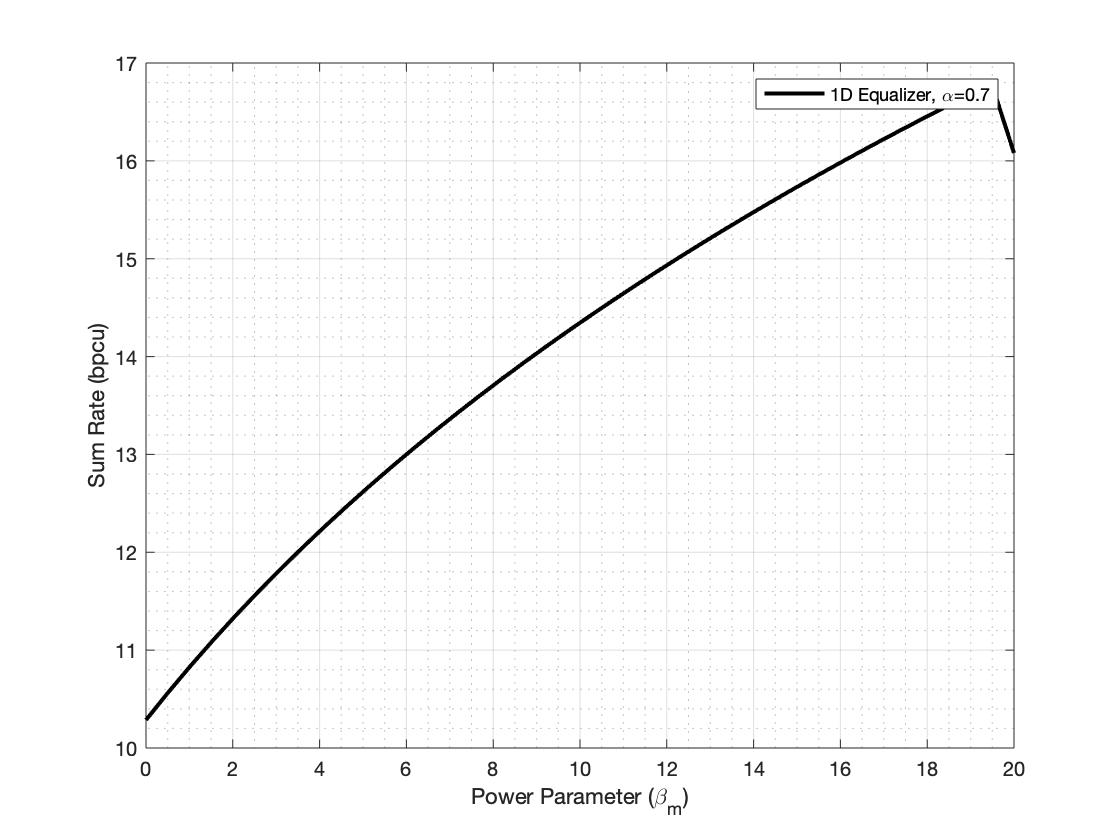

angel = strcat('\pi/', num2str(pi / mu));
if (mu == 0)
    angel = num2str(0);
end

name_a = '1D Equalizer';
name_b = '2D Equalizer';

name1 = strcat(name_a, ', \alpha=', num2str(alpha));
name2 = strcat(name_a, ', \eta=', num2str(eta), ', \mu=', angel);
name3 = strcat(name_b, ', \alpha=', num2str(alpha));
name4 = strcat(name_b, ', \eta=', num2str(eta), ', \mu=', angel);

x_label = 'Power Parameter (\beta_m)';
y_label = 'Sum Rate (bpcu)';

style = '-k';

figure;
plot(range, R1, style, 'DisplayName', name1);

xlabel(x_label, 'fontsize', 10);
ylabel(y_label, 'fontsize', 10);
set(gca, 'fontsize', 10);
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2);
legend();
grid on;
grid minor;

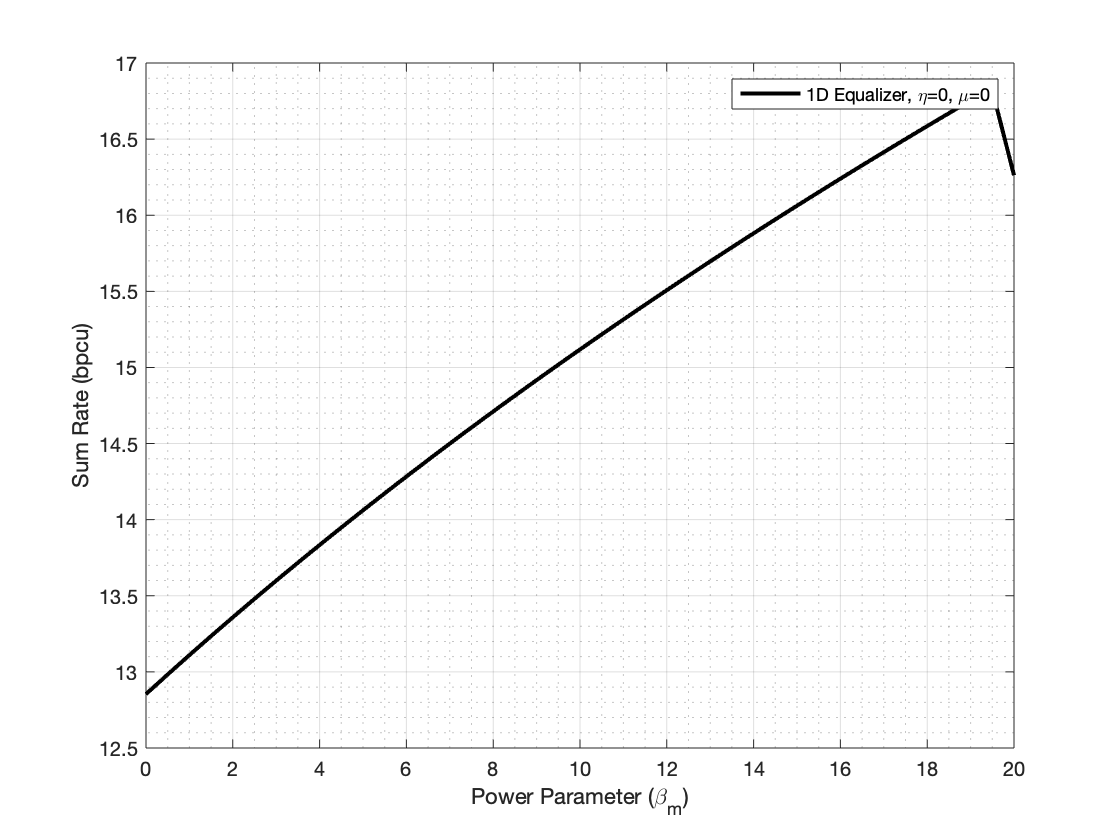



figure;
plot(range, R2, style, 'DisplayName', name2);

xlabel(x_label, 'fontsize', 10);
ylabel(y_label, 'fontsize', 10);
set(gca, 'fontsize', 10);
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2);
legend();
grid on;
grid minor;

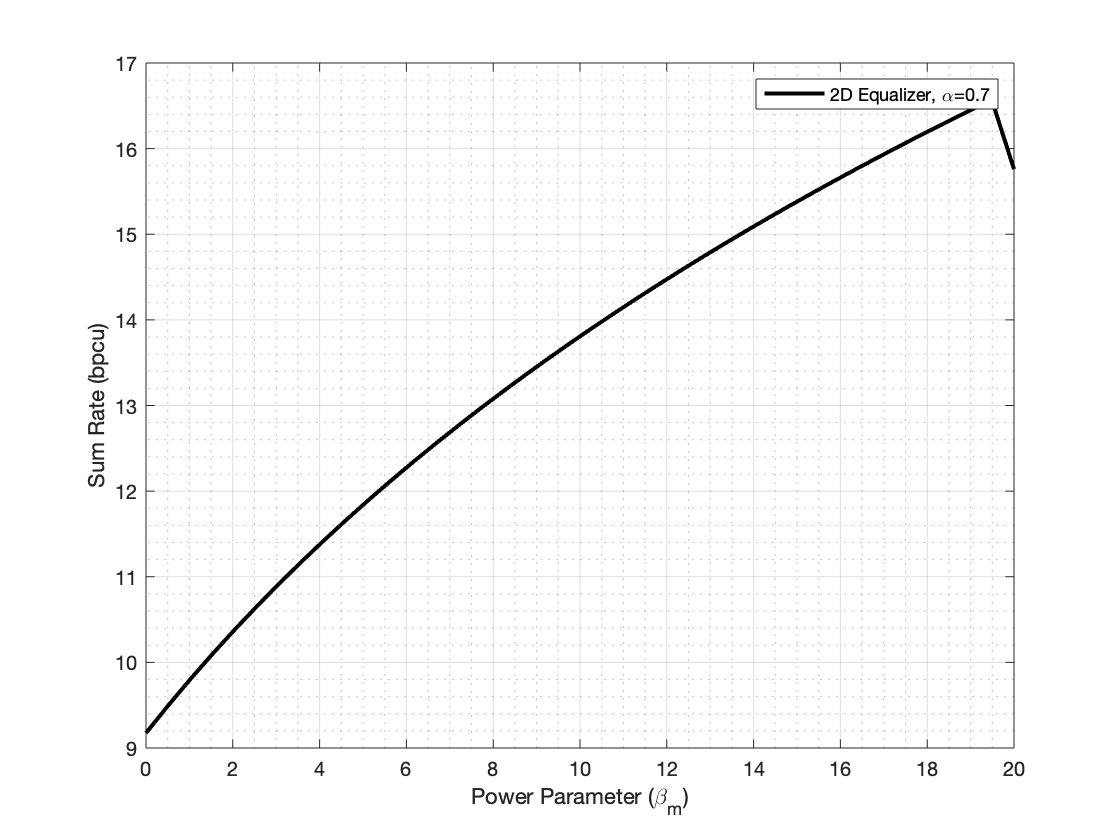


figure;
plot(range, R3, style, 'DisplayName', name3);

xlabel(x_label, 'fontsize', 10);
ylabel(y_label, 'fontsize', 10);
set(gca, 'fontsize', 10);
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2);
legend();
grid on;
grid minor;

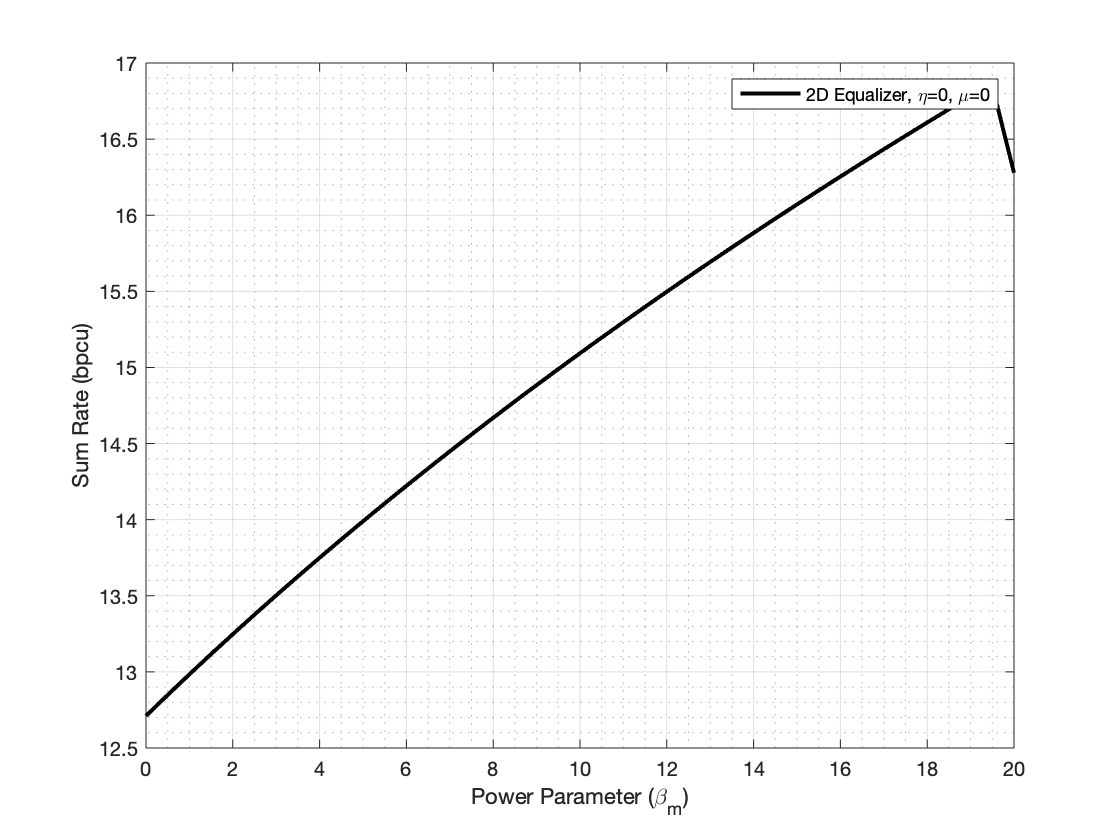



figure;
plot(range, R4, style, 'DisplayName', name4);

xlabel(x_label, 'fontsize', 10);
ylabel(y_label, 'fontsize', 10);
set(gca, 'fontsize', 10);
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2);
legend();
grid on;
grid minor;